**Lab 8**

First, import the data.

h5disp("data_highLumi_pt_1000_1200.h5")

HDF5 data_highLumi_pt_1000_1200.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attribut

h5disp("data_lowLumi_pt_1000_1200.h5")

HDF5 data_lowLumi_pt_1000_1200.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attribute

highLumi = h5read("data_highLumi_pt_1000_1200.h5","/data/block0_values")

highLumi = 	1.0e+03 *

    1.0147    1.0401    1.0239    1.0795    1.1675    1.0395    1.0729    1.1058    1.0126    1.0389    1.1654    1.1343    1.1081    1.1321    1.1700    1.1130    1.1212    1.0608    1.0220    1.0232    1.1411    1.1062    1.1623    1.1830    1.0634    1.1465    1.0977    1.0899    1.1354    1.0621    1.0800    1.0304    1.1670    1.1482    1.0818    1.1949    1.0195    1.0364    1.1585    1.0789    1.0323    1.1463    1.0087    1.0300    1.0680    1.1211    1.1111    1.0529    1.0649    1.1751
    0.0003   -0.0004   -0.0002   -0.0014    0.0000    0.0010    0.0011   -0.0002   -0.0007   -0.0012   -0.0007   -0.0011    0.0003   -0.0004   -0.0006    0.0006    0.0009   -0.0006    0.0008   -0.0004    0.0006    0.0011    0.0005   -0.0003    0.0016    0.0013    0.0016   -0.0004    0.0002   -0.0008    0.0006   -0.0001    0.0003   -0.0001    0.0004   -0.0000    0.0005    0.0003   -0.0013    0.0005    0.0001   -0.0005    0.0011    0.0001    0.0007    0.0005    0.0013    0.

lowLumi = h5read("data_lowLumi_pt_1000_1200.h5","/data/block0_values")

lowLumi = 	1.0e+03 *

    1.0191    1.0977    1.1095    1.1549    1.1061    1.1207    1.0870    1.1091    1.0186    1.0744    1.0440    1.0105    1.0461    1.0285    1.1992    1.1818    1.0708    1.1905    1.1693    1.0865    1.1953    1.0543    1.0628    1.0865    1.1392    1.0572    1.0918    1.1391    1.0716    1.0649    1.1840    1.0322    1.0789    1.1412    1.0717    1.1444    1.1517    1.0056    1.0064    1.0366    1.1169    1.1480    1.0733    1.1237    1.0102    1.0515    1.1408    1.1112    1.0487    1.1286
   -0.0001   -0.0010    0.0001    0.0008    0.0002    0.0014   -0.0006    0.0002   -0.0006   -0.0006    0.0001    0.0014    0.0012   -0.0011    0.0007   -0.0005    0.0003   -0.0008    0.0001   -0.0011    0.0000    0.0001   -0.0005    0.0010    0.0004   -0.0001    0.0002    0.0008    0.0015    0.0003   -0.0003    0.0003    0.0015   -0.0008   -0.0003   -0.0005   -0.0013   -0.0006   -0.0009   -0.0016   -0.0002   -0.0000   -0.0009    0.0014   -0.0008   -0.0006   -0.0004    0.0

I expect that the variables are in the same order and the same definitions, so I will not restate those.

hlPT = highLumi(1,:);
llPT = lowLumi(1,:);
hlETA = highLumi(2,:);
llETA = lowLumi(2,:);
hlPHI = highLumi(3,:);
llPHI = lowLumi(3,:);
hlMASS = highLumi(4,:);
llMASS = lowLumi(4,:);
hlEE2 = highLumi(5,:);
llEE2 = lowLumi(5,:);
hlEE3 = highLumi(6,:);
llEE3 = lowLumi(6,:);
hlD2 = highLumi(7,:);
llD2 = lowLumi(7,:);
hlANG = highLumi(8,:);
llANG = lowLumi(8,:);
hlT1 = highLumi(9,:);
llT1 = lowLumi(9,:);
hlT2 = highLumi(10,:);
llT2 = lowLumi(10,:);
hlT3 = highLumi(11,:);
llT3 = lowLumi(11,:);
hlT21 = highLumi(12,:);
llT21 = lowLumi(12,:);
hlT32 = highLumi(13,:);
llT32 = lowLumi(13,:);
hlKT = highLumi(14,:);
llKT = lowLumi(14,:);

I also need to import the old data, as well as my significance cuts. To reiterate, I am not giving descriptions of the variables since they are included in previous labs, specifically lab 7 which will also be attached together with this submission.

higgsData = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
qcdData = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');
hPT = higgsData(1,:);
qPT = qcdData(1,:);
hETA = higgsData(2,:);
qETA = qcdData(2,:);
hPHI = higgsData(3,:);
qPHI = qcdData(3,:);
hMASS = higgsData(4,:);
qMASS = qcdData(4,:);
hEE2 = higgsData(5,:);
qEE2 = qcdData(5,:);
hEE3 = higgsData(6,:);
qEE3 = qcdData(6,:);
hD2 = higgsData(7,:);
qD2 = qcdData(7,:);
hANG = higgsData(8,:);
qANG = qcdData(8,:);
hT1 = higgsData(9,:);
qT1 = qcdData(9,:);
hT2 = higgsData(10,:);
qT2 = qcdData(10,:);
hT3 = higgsData(11,:);
qT3 = qcdData(11,:);
hT21 = higgsData(12,:);
qT21 = qcdData(12,:);
hT32 = higgsData(13,:);
qT32 = qcdData(13,:);
hKTDELTAR = higgsData(14,:);
qKTDELTAR = qcdData(14,:);
massCutQ = (qMASS >= 125 & qMASS <= 128);
massCutH = (hMASS >= 125 & hMASS <= 128);
totalCutQ = (qANG(massCutQ) >= 0.1e-3 & qANG(massCutQ) <= 1e-3);
totalCutH = (hANG(massCutH) >= 0.1e-3 & hANG(massCutH) <= 1e-3);

We want to rescale the data set so it is comparable to the simulated data, meaning that the number of counts for the two is identical. We can see that for the low luminosity data, the number of points in a vector (number of counts) is 442, whereas for high luminosity data it is 4066. Simulated data has 100,000 points, meaning that my cuts cannot work as they are currently, due to them being vectors with indices that indicate whether the given data point should be taken or not.

Alternatively, I could simply impose the same conditions that I used on the simulated data to obtain cuts, and use them on the "real" data. Since the boundaries used were identical, this should still work, although it would yield a significantly smaller subset of data points.

massCutHL = (hlMASS >= 125 & hlMASS <= 128);
massCutLL = (llMASS >= 125 & llMASS <= 128);
totalCutHL = (hlANG(massCutHL) >= 0.1e-3 & hlANG(massCutHL) <= 1e-3);
totalCutLL = (llANG(massCutLL) >= 0.1e-3 & llANG(massCutLL) <= 1e-3);

Let's check the lengths of the cuts to make sure that they do not have too few points.

length(nonzeros(totalCutHL))

ans = 55

length(nonzeros(totalCutLL))

ans = 8

Admittedly, this is not a lot of points. However, it is rougly 1-2% of the data, which seems reasonable for large cut along two features. Let's also check just the lengths of the mass cuts to see if maybe increasing the range of the angularity cuts will provide a much higher number of data points.

length(nonzeros(massCutHL))

ans = 139

length(nonzeros(massCutLL))

ans = 11

That pretty much contains the answer. The mass cut has already taken out most of the points from the vectors, so the second cut has not really had a very strong impact. I think my cuts are decent enough to use, and we will see how well they perform on this data set.

*1) High luminosity data*

- *Focus on each feature of your event selection.*

- *Plot observed data, overlap with expected signal and background (normalized to observed yields) without event selection.*

Ah, so this question basically forces us to rescale the old data set anyway. We can do this by creating a fixed numbers of bins which can then be normalized by the total number of points in the set. Alternatively, normalize both histograms by using the normalization property of histogram objects in Matlab.

I will plot the features that are explored in the event selection, meaning features I used for my cuts, first without any cuts.

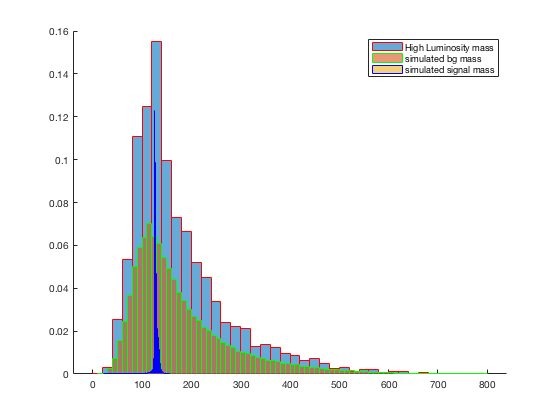

figure;
hold on
histogram(hlMASS,'Normalization',"probability",'EdgeColor',[1 0 0]);
histogram(qMASS,'Normalization',"probability",'EdgeColor',[0 1 0]);
histogram(hMASS,'Normalization',"probability",'EdgeColor',[0 0 1]);
legend('High Luminosity mass','simulated bg mass','simulated signal mass');
hold off

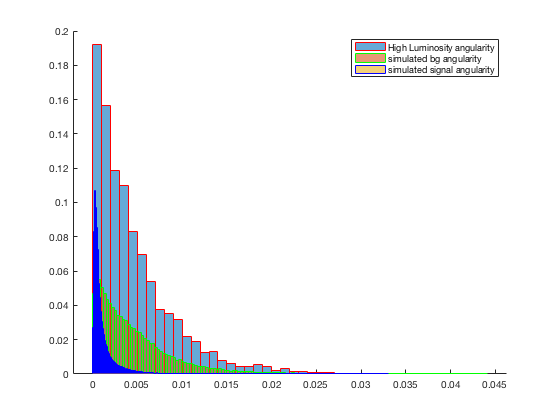

figure;
hold on
histogram(hlANG,'Normalization',"probability",'EdgeColor',[1 0 0]);
histogram(qANG,'Normalization',"probability",'EdgeColor',[0 1 0]);
histogram(hANG,'Normalization',"probability",'EdgeColor',[0 0 1]);
legend('High Luminosity angularity','simulated bg angularity','simulated signal angularity');
hold off

We can see that the normalized histograms look quite similar between the data sets, with the high luminosity data looking like a possible combination of the background and the signal (if renormalized afterwards), as would be expected.

- *Plot observed data, overlap with expected signal and background (normalized to observed yields) with optimal event selection.*

Now, we will plot the data after event selection cuts. The cuts use different 'vectors,' but they have the same formulas (which can be seen in the introduction of this file).

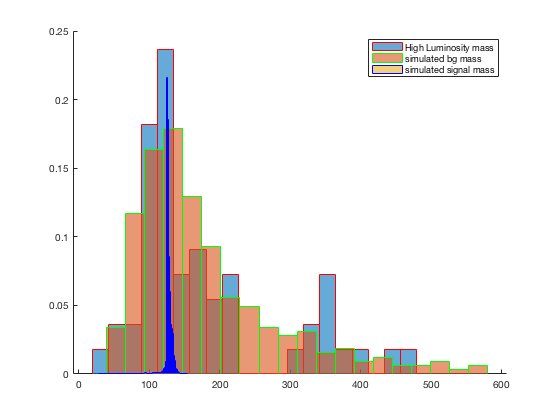

figure;
hold on
histogram(hlMASS(totalCutHL),'Normalization',"probability",'EdgeColor',[1 0 0],"NumBins",20);
histogram(qMASS(totalCutQ),'Normalization',"probability",'EdgeColor',[0 1 0],"NumBins",20);
histogram(hMASS(totalCutH),'Normalization',"probability",'EdgeColor',[0 0 1]);
legend('High Luminosity mass','simulated bg mass','simulated signal mass');
hold off

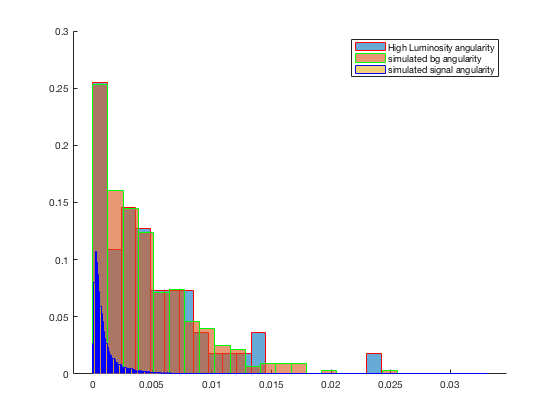

figure;
hold on
histogram(hlANG(totalCutHL),'Normalization',"probability",'EdgeColor',[1 0 0],"NumBins",20);
histogram(qANG(totalCutQ),'Normalization',"probability",'EdgeColor',[0 1 0],"NumBins",20);
histogram(hANG(totalCutH),'Normalization',"probability",'EdgeColor',[0 0 1]);
legend('High Luminosity angularity','simulated bg angularity','simulated signal angularity');
hold off

Although these histograms may initially look like they are not very convincing, recall that each bin represents a probability, and that the data after event selection does not have very many points.

Let's look at histograms just after the mass cut, for visual comparison.

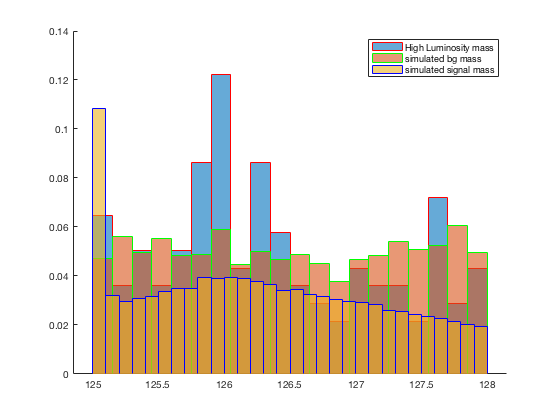

figure;
hold on
histogram(hlMASS(massCutHL),'Normalization',"probability",'EdgeColor',[1 0 0],"NumBins",20);
histogram(qMASS(massCutQ),'Normalization',"probability",'EdgeColor',[0 1 0],"NumBins",20);
histogram(hMASS(massCutH),'Normalization',"probability",'EdgeColor',[0 0 1]);
legend('High Luminosity mass','simulated bg mass','simulated signal mass');
hold off

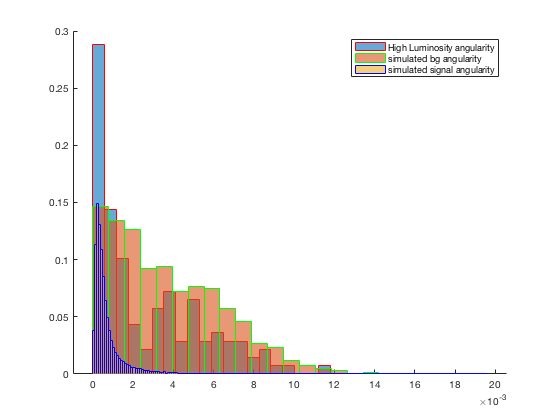

figure;
hold on
histogram(hlANG(massCutHL),'Normalization',"probability",'EdgeColor',[1 0 0],"NumBins",20);
histogram(qANG(massCutQ),'Normalization',"probability",'EdgeColor',[0 1 0],"NumBins",20);
histogram(hANG(massCutH),'Normalization',"probability",'EdgeColor',[0 0 1]);
legend('High Luminosity angularity','simulated bg angularity','simulated signal angularity');
hold off

These look a little bit less illuminating than the total cut results. I think the histograms are better than they might initially seem because although a lot of the background may be caught out, the "probability" of that background is still normalized, not matter how few points there are. Nonetheless, we can see that the high luminosity data, although I would state that we have kept most of the signal, does still contain what seems to be mostly background data (like in the tail parts of the total cut).

- *Evaluate observed significance and compare your results to expectation*

First, let's calculate the observed significance. I will assume that the observed data follows a Poisson distribution. After my event selection, there is some fraction of events I expect to keep if all of my data was just simulated background.

fract = length(nonzeros(totalCutQ))/100000

fract = 0.0032

Using this fraction, I can create a Poisson distribution for how many events this would correspond to in the high luminosity data, and use that Poisson distribution for integration to obtain my significance.

N_bg = fract * length(hlMASS) %just need the length of one of the vectors here

N_bg = 13.1738

N_hl_range = length(nonzeros(totalCutHL)) %number of counts in the event selection

N_hl_range = 55

N_tot = N_bg + N_hl_range

N_tot = 68.1738

poissonBG = makedist('Poisson',"lambda",N_bg);

Calculate significance.

prob = 1 - cdf(poissonBG,N_tot)

prob = 0

s_totalCutHL = icdf('Normal',1-prob,0,1)

s_totalCutHL = Inf

My N_hl_range is a lot larger than the new background mean, so it makes sense that the probability is 0, and therefore the significance is infinite. The result is a bit surprising if looked at the histogram plots, but I think it makes sense considering how many background points were cut out from the data set when compared to signal points.

The expected result is ~5.9 sigma (from lab7), and the obtained result here is ~infinite sigma. Of course, we cannot have a truly infinite sigma, but N_tot that we integrated was so far away from the mean that the probability for this to be produced by background is essentially zero. Although there is a very large difference between 5.9 sigma and infinity, I think the event selection worked well for the high luminosity data set.

*2) Low luminosity data*

- *Focus on each feature of your event selection.*

- *Plot observed data, overlap with expected signal and background (normalized to observed yields) without event selection.*

Exact same instructions as for part 1, except for low luminosity data. I will copy and paste the code from above, with appropriate substitutions.

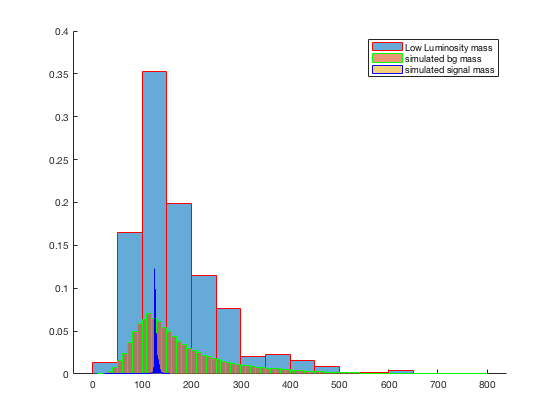

figure;
hold on
histogram(llMASS,'Normalization',"probability",'EdgeColor',[1 0 0]);
histogram(qMASS,'Normalization',"probability",'EdgeColor',[0 1 0]);
histogram(hMASS,'Normalization',"probability",'EdgeColor',[0 0 1]);
legend('Low Luminosity mass','simulated bg mass','simulated signal mass');
hold off

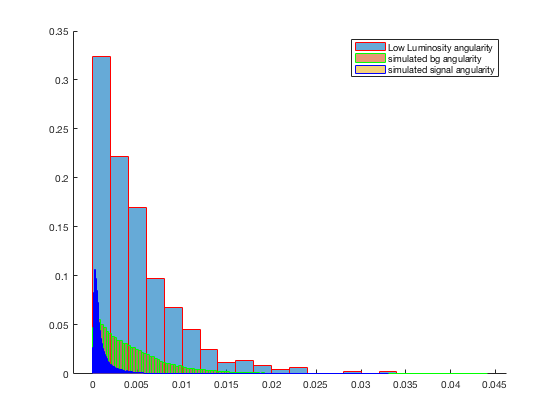

figure;
hold on
histogram(llANG,'Normalization',"probability",'EdgeColor',[1 0 0]);
histogram(qANG,'Normalization',"probability",'EdgeColor',[0 1 0]);
histogram(hANG,'Normalization',"probability",'EdgeColor',[0 0 1]);
legend('Low Luminosity angularity','simulated bg angularity','simulated signal angularity');
hold off

- *Plot observed data, overlap with expected signal and background (normalized to observed yields) with optimal event selection.*

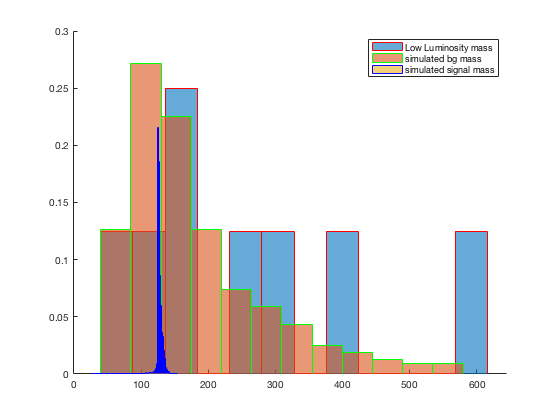

figure;
hold on
histogram(llMASS(totalCutLL),'Normalization',"probability",'EdgeColor',[1 0 0],"NumBins",12);
histogram(qMASS(totalCutQ),'Normalization',"probability",'EdgeColor',[0 1 0],"NumBins",12);
histogram(hMASS(totalCutH),'Normalization',"probability",'EdgeColor',[0 0 1]);
legend('Low Luminosity mass','simulated bg mass','simulated signal mass');
hold off

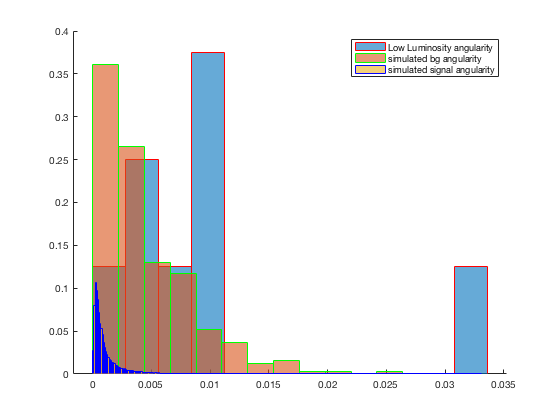

figure;
hold on
histogram(llANG(totalCutLL),'Normalization',"probability",'EdgeColor',[1 0 0],"NumBins",12);
histogram(qANG(totalCutQ),'Normalization',"probability",'EdgeColor',[0 1 0],"NumBins",12);
histogram(hANG(totalCutH),'Normalization',"probability",'EdgeColor',[0 0 1]);
legend('Low Luminosity angularity','simulated bg angularity','simulated signal angularity');
hold off

The low luminosity data does not look particularly great, specifically the angularity plot. I think this is largely because there are so few points left after the cut selection, but it does seem like it is still heavily impacted by background.

- *Evaluate observed significance and compare your results to expectation*

The calculations here, once again, reflect those in part 1.

N_bg = fract * length(llMASS) %just need one of the low lum vectors

N_bg = 1.4321

N_ll_range = length(nonzeros(totalCutLL)) %number of counts in the event selection

N_ll_range = 8

N_tot = N_bg + N_ll_range

N_tot = 9.4321

poissonBG = makedist('Poisson',"lambda",N_bg);

Calculate significance.

prob = 1 - cdf(poissonBG,N_tot)

prob = 2.7401e-06

s_totalCutLL = icdf('Normal',1-prob,0,1)

s_totalCutLL = 4.5455

The expected result is ~5.9 sigma (from lab7), and the obtained result here is ~4.55 sigma. The significance for the low luminosity is not that horrible, actually, but is clearly not as optimized as the high luminosity data. I suspect this is due to how much fewer data is present, thus deviations due to Poisson distributions, as well as imperfections in event selection, get magnified a lot. 

*3) 95% Confidence Level of signal yields*

- *In the low luminosity data, the observed significance is less than 5𝜎σ. We will calculate the 95% confidence level upper limit of signal yield.*

- *Evaluate the expected 95% confidence level upper limit*

I am going to integrate outwards from the middle point until I have covered 95% of the data. By "data" here I mean the Poisson distribution that is created for the expected number of counts. First, let's recreate the Poisson distribution in question.

N_bg = fract * length(hlMASS)

N_bg = 13.1738

poissonBG = makedist('Poisson',"lambda",N_bg);

I will make a plot of this distribution just so it is easier later to check where the boundaries that I found are and if they make sense.

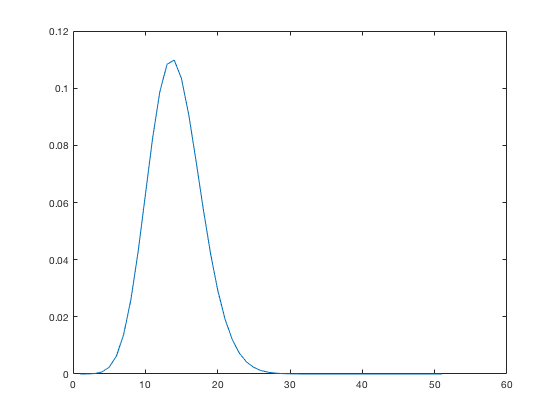

figure;
x = 0:50;
poissonPDF = pdf(poissonBG,x);
plot(poissonPDF);

Now, I want to integrate this distribution up until ~95% of it has been covered. Since this is normalized, I would just have to find it until probability is 0.95.

area = 0;
tt = 0;
while area < 0.95
    tt = tt+1;
    
end

- *Evaluate the observed 95% confidence level upper limit*

Similar to above, except here I am making the Poisson distribution from the observed number of counts.

- *Compare expectation to observation. Comment on your finding.*

It seems that my observed 95% confidence limit is a lot larger than the expected 95% confidence limit (factor of 5-10). I am not fully sure if I am calculating the right quantities, but if I am, this would suggest that the low luminosity data is maybe not fit well by the event selection? The confidence limits increase quite a lot (factor of ~3) just between the data sets, but there is another factor of ~2 if I further use the event selection. I am unsure what this means and if I am even doing this correctly, so I will think upon this further.